# **SISTEMAS DE CONTROL II                              **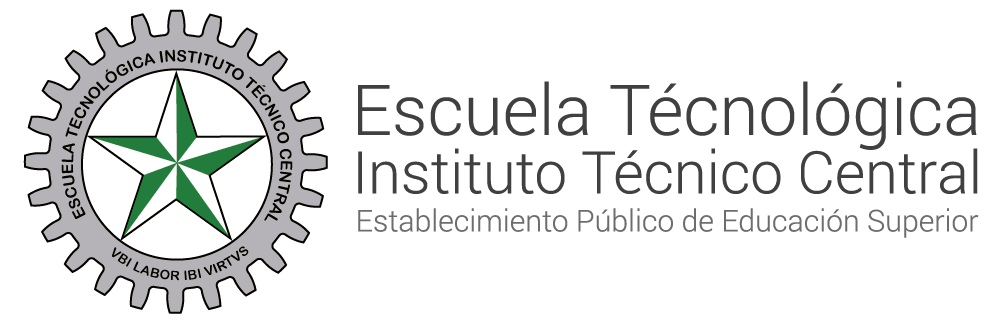

# **Transformada Z**

#### Autor ING. Jheyson Fabian Villavisan Buitrago MS.c

#### Coautora: Yenny Michel Wilches Zarate

**Objetivo:** El objetivo de esta clase es proporcionar a los estudiantes una **comprensión **profunda y práctica de la **Transformada Z** y su relevancia en el análisis y diseño de sistemas lineales e invariantes en el tiempo. Al finalizar la clase, los participantes estarán capacitados para:

Comprender los fundamentos teóricos de la Transformada Z y su relación con el análisis de señales y sistemas discretos.

Dominar los conceptos clave, como la región de convergencia, la relación entre la Transformada Z y la Transformada de Laplace, y las propiedades importantes de la Transformada Z.

# **Rampa.**

- **Definición:**

La función rampa, denotada como $y\left(k\right)$, es una función definida como:


$$r\left(t\right)=\left\lbrace \begin{array}{ll}
0 & \mathrm{si}\;k<0\\
k & \mathrm{si}\;k\ge 0
\end{array}\right.$$


En sistemas digitales, su **transformada Z** es:

Para la rampa discreta, $r\left\lbrack k\right\rbrack =k\;\textrm{para}\;k\ge 0,$ usando la definición de la transformada Z:

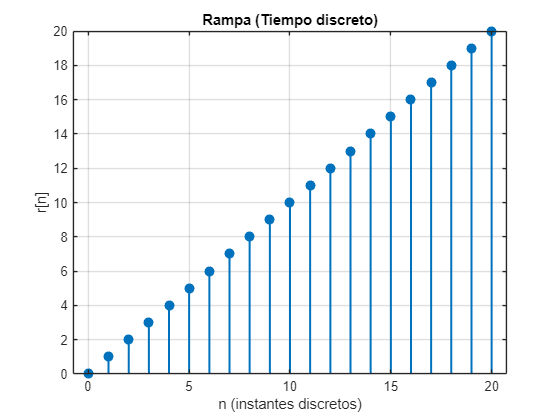

n = 0:20; 
r = n;
figure;
stem(n, r, 'filled', 'LineWidth', 1.5);
title('Rampa (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('r[n]');
grid on;


$$\begin{array}{l}
R\left(z\right)=\sum_{k=0}^{\infty } r\left\lbrack k\right\rbrack \cdot z^{-k} \\
R\left(z\right)=\sum_{k=0}^{\infty } k\cdot z^{-k} 
\end{array}$$


Para resolver, se utiliza una propiedad derivada de la serie geométrica básica:


$$\sum_{k=0}^{\infty } x^k =\frac{1}{1-x}\;\textrm{para}\;\left|x\right|<1$$


Se toma la derivada con respecto a $x$ en ambos lados para introducir el término de $k$:


$$\frac{d}{\textrm{dx}}\left(\sum_{K=0}^{\infty } x^k \right)=\frac{d}{\textrm{dx}}\left(\frac{1}{1-x}\right)$$


Resolviendo:

- En la sección izquierda: 


$$\frac{d}{\textrm{dx}}\left(\sum_{K=0}^{\infty } x^k \right)=\sum_{K=0}^{\infty } {\textrm{kx}}^{k-1}$$


- En la sección derecha: 


$$\frac{d}{\textrm{dx}}\left(\frac{1}{1-x}\right)=\frac{1}{{\left(1-x\right)}^2 }$$


Por lo tanto:


$$\sum_{K=0}^{\infty } {\textrm{kx}}^{k-1} =\frac{1}{{\left(1-x\right)}^2 }$$


Se multiplica por $x$ para ajustar la potencia: 


$$\sum_{K=0}^{\infty } {\textrm{kx}}^k =\frac{x}{{\left(1-x\right)}^2 }$$


En la transformada Z, se obtiene $x=z^{-1} \ldotp$ Sustituyendo:


$$\sum_{K=0}^{\infty } {\textrm{kz}}^{-k} =\frac{z^{-1} }{{\left(1-z^{-1} \right)}^2 }$$


Simplificando:


$$R\left(z\right)=\frac{z^{-1} }{{\left(1-z^{-1} \right)}^2 }$$


Multiplicar el numerador y denominador por $z^2$ para eliminar los términos $z^{-1}$:


$$\mathit{\mathbf{R}}\left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}}{{\left(\mathit{\mathbf{z}}-1\right)}^2 }$$


syms f(k) a T
A=k;
B=T;
f(k) = A*B;
F = ztrans(f,z)

$$F = \frac{T\,z}{{\left(z-1\right)}^{2}}$$